% Pb 1)
x = 1 : 10;
y = sin(1 : 10);

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4; x.^5];

x_approx = x(1) : (x(length(x)) - x(1)) / 100 : x(length(x));

y_approx = metoda_patratelor(x, y, phi, x_approx)

y_approx =     0.8059    0.9421    1.0489    1.1288    1.1840    1.2168    1.2292    1.2233    1.2008    1.1638    1.1138    1.0525    0.9816    0.9024    0.8163    0.7247    0.6289    0.5299    0.4289    0.3269    0.2248    0.1235    0.0239   -0.0734   -0.1677   -0.2583   -0.3447   -0.4264   -0.5029   -0.5739   -0.6389   -0.6978   -0.7504   -0.7963   -0.8355   -0.8679   -0.8934   -0.9120   -0.9238   -0.9287   -0.9270   -0.9188   -0.9041   -0.8833   -0.8565   -0.8240   -0.7862   -0.7431   -0.6953   -0.6431


% Pb 2)
x=[-1.024940; -0.949898; -0.866114; -0.773392; -0.671372; -0.559524;...	
    -0.437067; -0.302909; -0.159493; -0.007464];
y=[-0.389269; -0.322894; -0.265256;	-0.216557;	-0.177152; -0.147582;...
    -0.128618; -0.121353;	-0.127348; -0.148895];

A=[y.^2, x.*y, x, y, ones(size(x))];
bv=x.^2;
coef=A\bv;
a=coef(1); b=coef(2); c=coef(3); d=coef(4); e=coef(5);

err=sum((a*y.^2+b*x.*y+c*x+d*y+e-x.^2).^2)^(1/2)

err = 0.0011

err_eliptic=norm(a*y.^2+b*x.*y+c*x+d*y+e-x.^2)

err_eliptic = 0.0011

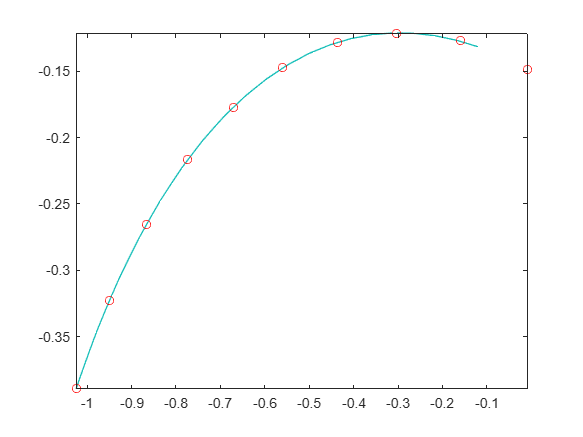


u=linspace(min(x),max(y),20);
v=linspace(min(y),max(y),20);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]);
hold on;
plot(x,y,'ro');
hold on


A2=[y,ones(size(x))];
coef2=A2\bv;
a=coef2(1)

a = -3.8549

e=coef2(2)

e = -0.3510


err2=sum((a*y+e-x.^2).^2)^(1/2)

err2 = 0.3433

err_parabolic=norm(a*y+e-x.^2)

err_parabolic = 0.3433

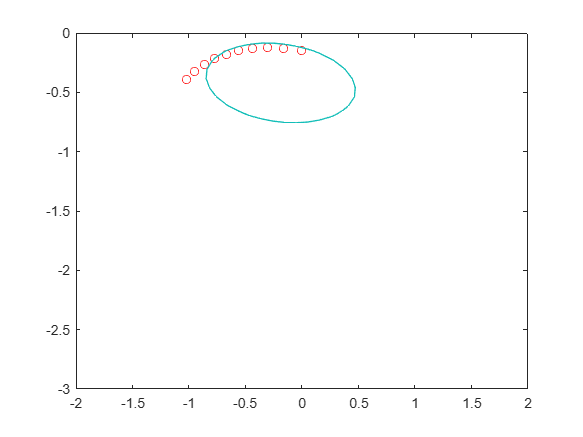


figure()
plot(x,y,'ro');
hold on
u=linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2+b*X.*Y+c*X+d*Y+e-X.^2;
contour(X,Y,Z,[0,0]);


% Pb 4)
y = [ 75.995  91.972 105.711 123.203 131.669 150.697 ...
    179.323 203.212 226.505 249.633 281.422 308.786]';
t = (1900:10:2010)';

x = (1890:1:2019)';
w = [1975,2015]; 

c=polyfit(t,y,3);

mt=mean(t); st=std(t);
s=(t-mt)/st;
xs=(x-mt)/st;

cs=polyfit(s,y,3);

zs=polyval(cs,xs)

zs =    68.7502
   69.6168
   70.5042
   71.4122
   72.3409
   73.2903
   74.2602
   75.2506
   76.2616
   77.2930


est=polyval(cs,(w-mt)/st)

est =   212.5513  325.2561



cs=polyfit(t,log(y),1);
K=exp(cs(2)); 
lambda=cs(1);

fm=@(t) K*exp(lambda*t);
zs=fm(x)

zs =    71.3824
   72.2872
   73.2034
   74.1313
   75.0709
   76.0224
   76.9860
   77.9618
   78.9499
   79.9506


est=fm(w)

est =   208.2319  344.6277


function res = metoda_patratelor(x, y, functions, points)
    phi = functions(x);
    phi_approx = functions(points);    
    n = length(x);
    [n, ~] = size(phi);
    for i = 1 : n
        for j = 1 : n
            A(i, j) = phi(i, :) * transpose(phi(j, :));
        end
        B(i, 1) = phi(i, :) * transpose(y);
    end
    a = linsolve(A, B);
    res = transpose(a) * phi_approx;
end